# Calculos Campo

% Campo magnetico
r =6% radio del tubo en el que esta el juego 

r = 6

I =40000% corriente

I = 40000

h =50% altura

h = 50

%N =5% num. espriras
g = 9.81; % gravedad
M0 = 4*pi*1e-7; % permeabilidad del aire (miu)
masa = (130 + 50 )*40 % Kg

masa = 7200

tmax = sqrt((2*h)/g);
paso = 0.1; %  paso
t=0:paso:tmax; % rango en el tiempo
% yi = 0; %ayuda
%vel = t.*g;% velocidad por segundo
vel = @(t) t.*g

vel = function_handle with value:
    @(t)t.*g


R = 0.0000001;
achiq = 0.1;

ti = 0;
vi = 0;


% Calculo Campo
%[z,B]=Calculo_campo(paso,t,h,g,M0,I,r) % llamada de la funcion
z = @(t) h + vel(0) .* t + (0.5.*-g.*t.^2);% Posicion en z
%z = @(t) (g*t.^2)/2;% Posicion en z
B = @(z) (M0*I*r.^2)./(2*(r.^2+z.^2).^(3/2)); %Campo

%z = @(t) (t.*g).*t+(1/2).*g.*t.^2;

z1 = z(t)

z1 =    50.0000   49.9509   49.8038   49.5585   49.2152   48.7737   48.2342   47.5966   46.8608   46.0269   45.0950   44.0649   42.9368   41.7105   40.3862   38.9637   37.4432   35.8246   34.1078   32.2930   30.3800   28.3689   26.2598   24.0526   21.7472   19.3438   16.8422   14.2425   11.5448    8.7490    5.8550    2.8629


b1 = B(z1)

b1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0004    0.0008    0.0015    0.0031


V = vel(t)

V =          0    0.9810    1.9620    2.9430    3.9240    4.9050    5.8860    6.8670    7.8480    8.8290    9.8100   10.7910   11.7720   12.7530   13.7340   14.7150   15.6960   16.6770   17.6580   18.6390   19.6200   20.6010   21.5820   22.5630   23.5440   24.5250   25.5060   26.4870   27.4680   28.4490   29.4300   30.4110


A = pi.*r^2

A = 113.0973


fem = @(t) vel(t).*B(z1).*h

fem = function_handle with value:
    @(t)vel(t).*B(z1).*h


FEM = fem(t)

FEM =          0    0.0003    0.0007    0.0011    0.0015    0.0019    0.0023    0.0028    0.0034    0.0040    0.0047    0.0056    0.0065    0.0077    0.0091    0.0109    0.0130    0.0157    0.0192    0.0238    0.0299    0.0382    0.0500    0.0670    0.0928    0.1336    0.2019    0.3246    0.5642    1.0779    2.2597    4.6823


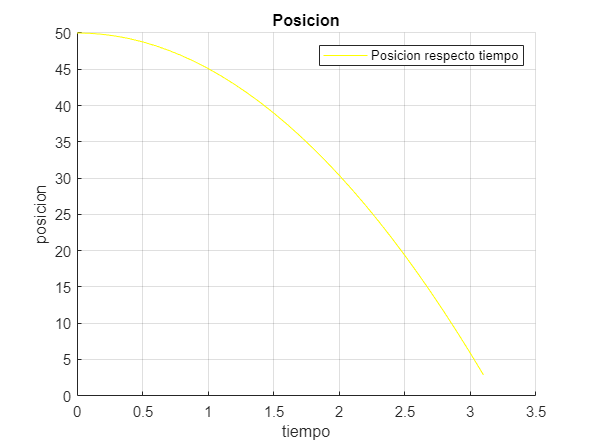

%torque magnetico
%torque = mdm*b1*sin(90);

%Magnetic dipole moment
%%%%mdm = I*A;   mdm = I*A^2*pi 

%motional emf
%e = -b1*V*h;

%flujo magnetico

%mflux = b1*A*cos(90);

%ley de Faraday
%ELF = mflux/t;
%ley de Lenz 
%LL = -LF;



% Grafica la Posicion respecto al tiempo 
clf;
hold on
plot(t,z1,'y')
title("Posicion")
legend("Posicion respecto tiempo")
xlabel("tiempo")
ylabel("posicion")
grid on
hold off

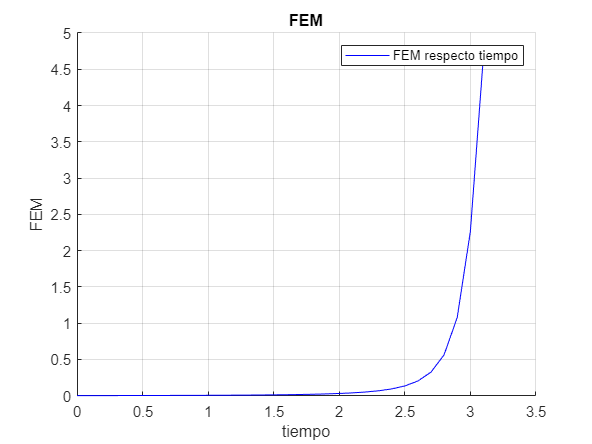


% Grafica fem respecto al tiempo
clf;
hold on
plot(t,FEM,'b')
title("FEM")
legend("FEM respecto tiempo")
xlabel("tiempo")
ylabel("FEM")
grid on
hold off

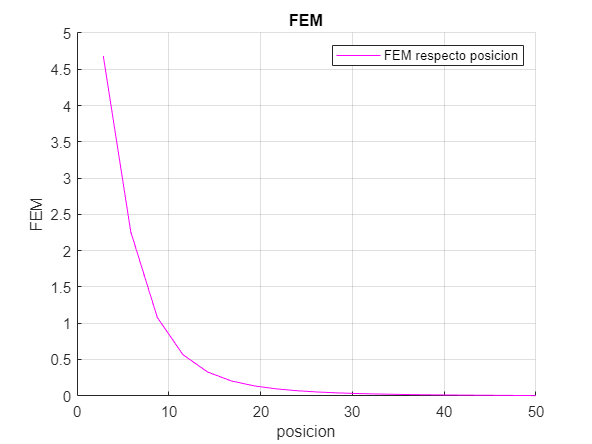


% Grafica fem respecto a la posicion
clf;
hold on
plot(z1,FEM,'m')
title("FEM")
legend("FEM respecto posicion")
xlabel("posicion")
ylabel("FEM")
grid on
hold off


% Grafica la fem respecto a la Velocidad 
clf;
hold on
plot(V,FEM,'g')
title("FEM")
legend("FEM respecto velocidad")
xlabel("velocidad")
ylabel("FEM")
grid on
hold off

% mdm = I*A^2*pi 
% Flujo del campo magnetico
% A = pi*r^2; %Superficie
% vel = % velocidad por segundo
% fi = (M0.*N.*I./z).*A; %Flujo magnetico
% fi = B.*A %Flujo 
% Integrar 
% plot(z,fi,'*b');
% plot(t,fi,'-m-);
% grid on

% (Fg - Fz) / m         (Fg(masa*gravedad) - Fz(%B.*A -> Flujo(fi))) / m
% a = (Fz + Fg) / m % aceleracion
% I =   %Corriente 
% L = %Corriente Inducida 
% F = m * a % masa por aceleracion 
% Fuerza necesaria para frenarlo

% disp("Fuerza Neta")
%F = masa * g   Fmg
% F = I * 2 * 
% fem instantanea, B*A (sin velocidad por que es el punto 0; instantanea)

%----------------------------------------------------------------------------------
% Fuerza 
Fmg = m*g %masa*gravedad

Fmg = 9810


% Momento magnetico
M = @(I) I.*A %corriente * Area

M = function_handle with value:
    @(I)I.*A



%  aiuda
%b1 = 1000;

%Flujo magnetico
%fmag = B*A %es el simbolo del circulito con una raya en medio vertical)

%Voltaje (derivada del flujo)
%Voltaje = diff(fmag) %diferencial de flujo magnetico

%Corriente Inducida
%IInducida = Voltaje/r %voltaje/radio

%Fuerza del Campo  -------ESTO LO DEFINE EL IMAN EN CANVAS O INVENTAMOS UN VALOR REALISTA TAMAÑO
%FB = (B*M)./z %Campo*Permeabilidad del espacio / posicion en z cada segundo 

%Aceleracion
%a = (FB - Fmg)./m %Fuerza del campo - Fuerza / masa

%Voltaje en el siguiente segundo

%Campo Inducido
%BInducido = M0*IInducida./2.*z %(Permeabilidad*Corriente Inducida/ 2 * posicion siguiente z segun el tiempo)

%Fuerza del campo
%[t,fem] = ode45(@())


%flujo = @(B) B(t).*A;
%fem = @(flujo) -(flujo(B)-flujo(B-1))/dt; %Le puse un -
%I_inducida = @(fem) fem/R;
%B_inducida = @(I_inducida) M0.*I_inducida(fem).*achiq.^2./( 2.*(achiq.^2 + z(t-1).^2).^(3/2) );
%momentoSol = @(I_inducida) I_inducida(fem).*achiq.^2.*pi;
%Fz(i) = (mu0/4*pi)*momento*momentoSol/z(i-1)^2;
%Fz = @(B_inducida) B_inducida(I_inducida).*M./z(t-1);
%acel = @(Fz) (-Fz(B_inducida) + m.*g)./m;
%jerk = @(acel) (acel(Fz) - acel(Fz-1))/dt
%vz = @(acel) vz(acel-1)+acel(Fz)*dt;%%%
%zZ = @() zZ(i-1) + (vz(acel)*dt) + 0.5*acel(Fz)*dt^2;
%tT = @() t(i-1) + dt;
%vzz(i) = vzz(i-1)+g*dt;
%zz(i) = zz(i-1)+vzz(i)*dt + 0.5*g*dt^2;

%JERK = jerk(acel) uyyyyyy

%b1 = B(z1)
%z1 = z(t);

%plot(t,jerk());

%hold on
z = h; 
h = 0.1;
I = 1000;
M = I*A;
N = 2002003;


aceleracion = @(x,Vx) -g + ((27*(z^3)*(M0^3)*(M^2)*(r^6)*(Vx^2)*A)/(8*masa*(R^2)*(r^2+z^2)^(15/2)))*N; 
velocidad = @(Vx,ace) Vx + ace*h;

[tt,acelacel,velvel,pospos] = met_RK4Mod(aceleracion,velocidad, h, ti, tmax, aceleracion(z,vi), vi, z);


$$\textrm{FEM}=\frac{3\mu_0 \mu {a^2 \textrm{xV}}_x }{2{\left(a^2 +x^2 \right)}^{\frac{5}{2}} }$$


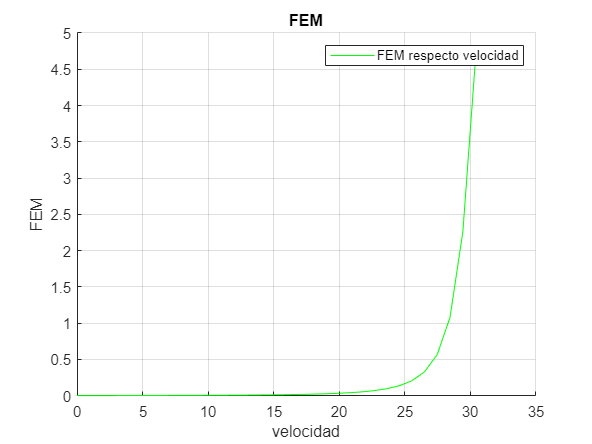

fem = @(x,Vx) (3.*M0.*M.*(r.^2).*r.*Vx)/2.*(r.^2+z.^2).^(5/2);
%Se grafica el resultado
tiledlayout(1,4);

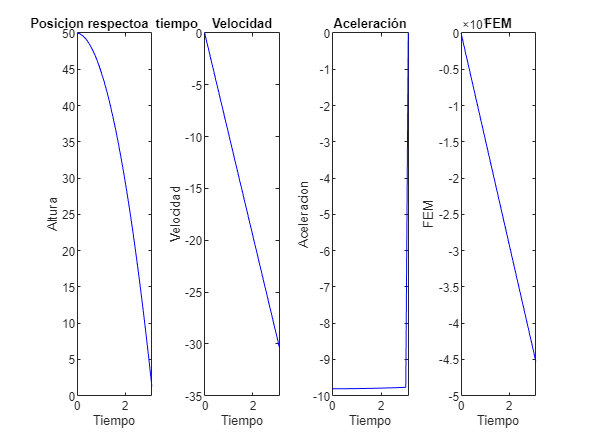

nexttile
plot(t,pospos,'b')
axis auto;
title('Posicion respectoa  tiempo')
xlabel('Tiempo')
ylabel('Altura')
nexttile
plot(t,velvel,'b')
axis auto;
title('Velocidad')
xlabel('Tiempo')
ylabel('Velocidad')
nexttile
plot(t,acelacel,'b');
axis auto;
title('Aceleración')
xlabel('Tiempo')
ylabel('Aceleracion')
nexttile
plot(t,fem(pospos,velvel),'b');
axis auto;
title('FEM')
xlabel('Tiempo')
ylabel('FEM')

Solución Numérica por el m**étodo de RK Grado 4.**

function [x,acel,vel,pos] = met_RK4Mod(f1,f2, h, inicio, fin, acel_inicial, vel_inicial, pos_inicial)
    x = inicio:h:fin;
    acel = zeros(1,length(x));
    vel = zeros(1,length(x));
    pos = zeros(1,length(x));
    acel(1) = acel_inicial;
    vel(1) = vel_inicial;
    pos(1) = pos_inicial;
    for i=1:(length(x)-1)
        k1 = f1(pos(i), vel(i));
        k2 = f1(pos(i)+(1/2*h), vel(i)+(1/2*k1*h));
        k3 = f1(pos(i)+(1/2*h), vel(i)+(1/2*k2*h));
        k4 = f1(pos(i)+h, vel(i) + k3*h);
        vel(i+1) = vel(i)+1/6*(k1+2*k2+2*k3+k4)*h;
        
        acel(i) = f1(pos(i), vel(i)); 
        
        l1 = f2(vel(i),acel(i));
        l2 = f2(vel(i)+(1/2*h),acel(i)+(1/2*h*l1));
        l3 = f2(vel(i)+(1/2*h),acel(i)+(1/2*h*l2));
        l4 = f2(vel(i)+h,acel(i)+(l3*h));
        pos(i+1) = pos(i)+1/6*(l1+2*l2+2*l3+l4)*h;
    end
end